# **MSD3 2019-20 **

## **Exo 4. Strains**

The strain state of a body at point O is defined by the displacement gradient tensor $\tilde{e}$ defined in the coordinate system $\left(O,x_1 ,x_2 ,x_3 \right)$ by the matrix $\bar{\bar{e} } =\left\lbrack \begin{array}{ccc}
-1 & 0 & 2\\
2 & -2 & -1\\
2 & -1 & 3
\end{array}\right\rbrack \times {10}^{-3}$

(1)   Show that considering a small deformation is a relevant hypothesis. Calculate the matrix of the small strain tensor in O.

(2)   Find the mean strain and elementary volumic variation.

(3)   Find the distortion of  the following angles  $\left(x_1 ,x_2 \right)$,$\left(x_2 ,x_3 \right)$ and $\left(x_3 ,x_1 \right)$

(4)   Specify the strain state corresponding to the tensor  $\tilde{e}$? Justify. 

(1) Second order values are negligeable. $\tilde{\varepsilon} =\frac{e^t +e}{2}$

e=[-1 0 2;2 -2 -1;2 -1 3]*1e-3;
eps=(e'+e)/2

eps =    -0.0010    0.0010    0.0020
    0.0010   -0.0020   -0.0010
    0.0020   -0.0010    0.0030


(2) $\epsilon_m =\textrm{trace}\;\left(\epsilon \right)/3$ and $\Delta V/V=\textrm{trace}\left(\epsilon \right)$

eps_m=trace(eps)/3

eps_m = 0

DV_V=trace(eps)

DV_V = 0

(3) ${\delta \theta }_{12} =2\varepsilon_{12}$

dtheta_12=2*eps(1,2)

dtheta_12 = 0.0020

dtheta_13=2*eps(1,3)

dtheta_13 = 0.0040

dtheta_23=2*eps(2,3)

dtheta_23 = -0.0020

(4) we have already a nil volume strain, let's find the rotation component, knowing that if $\overrightarrow{\omega} =\left\lbrack \begin{array}{c}
p\\
q\\
r
\end{array}\right\rbrack$then $\bar{\bar{\omega} } =\left\lbrack \begin{array}{ccc}
0 & -r & q\\
r & 0 & -p\\
-q & p & 0
\end{array}\right\rbrack$

omega=(e'-e)/2

omega = 	1.0e+-3 *

         0    1.0000         0
   -1.0000         0         0
         0         0         0


rotation around $x_3$of ${-10}^{-3} \;\textrm{rd}$

## Exo 5. Thermomechanics

We consider a fully rigid Invar [[1]](about:blank<#_ftnref1>) plate in which a parallelepipedic hole has been drilled.  Its depth is 10 mm and the two other dimensions are 10 x 10.005 mm. A 10 mm bronze cube is inserted in the hole. The frictions forces are negligible and the modules of bronze are : $E=140\;\textrm{GPa}$, $\nu =0\ldotp 3$    

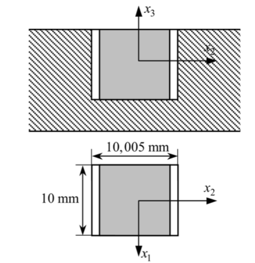

**1.**  The top face of the cube is compressed under a uniform force of 12000 N.

**1.1** Supposing contact between the bronze cube and the plate along $x_2$, calculate the principal stresses in the cube. What can we conclude ? 

**1.2** Calculate the real stresses in the cube.

**1.3** For which value of the applied force the cube is just in contact with the plate along  $x_2$? 

**2.** Initially at a temperature of 20°C, both the cube and the plate are then heated to 60°C. The thermal expansion coefficient of Invar is supposed nil, and that of bronze is  $\alpha =18\times {10}^{-6} \;{\mathrm{K}}^{-1}$.

**2.1** Calculate the stresses in the cube. 

**2.2** The system is still heated to 60°C, but in addition a 12000 N force is added on the top face. Calculate the stresses and strains. 

[[1]](about:blank<#_ftnref1>) Invar, also known generically as FeNi36 is a nickel steel alloy notable for its uniquely low coefficient of thermal expansion (*Wikipedia*)

**1.1 **Boundary conditions : $\sigma_3 =-\frac{F}{S}$, contact along $x_2$, so that $\epsilon_2 =\frac{L_g -L}{L}$ and $\epsilon_1 =0$

syms  F S Lg L s1 s2 s3 e1 e2 e3 nu E
s3=-F/S;
e1=0;
e2=(Lg-L)/L;
A1=e1*E-(s1-nu*(s2+s3))==0;
A2=e2*E-(s2-nu*(s3+s1))==0;
A3=e3*E-(s3-nu*(s1+s2))==0;
[A,B]=equationsToMatrix([A1,A2,A3], [s1,s2,e3])

$$A = \left(\begin{array}{ccc} -1 & \nu & 0\\ \nu & -1 & 0\\ \nu & \nu & \text{E} \end{array}\right)$$

$$B = \left(\begin{array}{c} \frac{F\,\nu }{S}\\ \frac{\text{E}\,\left(L-\mathrm{Lg}\right)}{L}+\frac{F\,\nu }{S}\\ -\frac{F}{S} \end{array}\right)$$

K=inv(A)*B

$$K = \begin{array}{l} \left(\begin{array}{c} \frac{\nu \,\sigma_{1}}{\nu^{2}-1}+\frac{F\,\nu }{\sigma_{3}}\\ \frac{\sigma_{1}}{\nu^{2}-1}+\frac{F\,\nu^{2}}{\sigma_{3}}\\ \frac{\nu \,\sigma_{1}}{\sigma_{2}}-\frac{F}{\text{E}\,S}+\frac{F\,\nu^{2}}{S\,\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\text{E}\,\left(L-\mathrm{Lg}\right)}{L}+\frac{F\,\nu }{S}\\ \sigma_{2}=\text{E}-\text{E}\,\nu \\ \sigma_{3}=S\,\left(\nu^{2}-1\right) \end{array}$$

F=12000; S=1e-4;E=140e9; nu=0.3; Lg=10.005e-3;L=10e-3;
eval(K)

ans = 	1.0e+07 *

   -2.8352
    2.5495
   -0.0000



eval(K(3))

ans = -8.5102e-04

Not possible since tension along $x_2$

**1.2** in the end, there is no contact along $x_2$, then the new boundary conditions are : $\sigma_2 =0$, $\epsilon_1 =0$ and $\sigma_3 =-\frac{F}{S}$

clear all
syms  F S Lg L s1 s2 s3 e1 e2 e3 nu E
s3=-F/S;
e1=0;
s2=0;
A1=e1*E-(s1-nu*(s2+s3));
A2=e2*E-(s2-nu*(s3+s1));
A3=e3*E-(s3-nu*(s1+s2));
[A,B]=equationsToMatrix([A1,A2,A3], [s1,e2,e3])

$$A = \left(\begin{array}{ccc} -1 & 0 & 0\\ \nu & \text{E} & 0\\ \nu & 0 & \text{E} \end{array}\right)$$

$$B = \left(\begin{array}{c} \frac{F\,\nu }{S}\\ \frac{F\,\nu }{S}\\ -\frac{F}{S} \end{array}\right)$$

K=inv(A)*B

$$K = \left(\begin{array}{c} -\frac{F\,\nu }{S}\\ \frac{F\,\nu }{\text{E}\,S}+\frac{F\,\nu^{2}}{\text{E}\,S}\\ \frac{F\,\nu^{2}}{\text{E}\,S}-\frac{F}{\text{E}\,S} \end{array}\right)$$

F=12000; S=1e-4;E=140e9; nu=0.3; Lg=10.005e-3;L=10e-3;
s1=eval(K(1))/1e6 % in MPa

s1 = -36

e2=eval(K(2))

e2 = 3.3429e-04

e3=eval(K(3))

e3 = -7.8000e-04

1.3 Same boundary conditions, therefore, one can write :$\frac{F^{\left(3\right)} }{{\epsilon_2 }^{\left(3\right)} }=\frac{F^{\left(2\right)} }{{\epsilon_2 }^{\left(2\right)} }$, then $F^{\left(3\right)} =\frac{F^{\left(2\right)} }{{\epsilon_2 }^{\left(2\right)} }\cdot {\epsilon_2 }^{\left(3\right)}$

F_3=F*(Lg-L)/L/K(2);
F_3=eval(F_3)

F_3 = 1.7949e+04

**2.1 **We apply a temperature difference of $\Delta T=40\textrm{°C}$. The cubes tends to expend, it is possible along $x_3$, not possible along $x_1$. We have to suppose if we have or not contact along $x_2$. For this one can calculate the free thermal expansion $\varepsilon_T =\alpha \Delta T$and compare to the quantity $\frac{L_g -L}{L}$ représenting the maximum expansion along $x_2$.

eps2_max=(Lg-L)/L

eps2_max = 5.0000e-04

alpha=18e-6; DT=40;
eps_T=alpha*DT

eps_T = 7.2000e-04

Since the real expansion along $x_2$ will be higher than $\epsilon_T$ owing to Poisson effects due to the fact that $\epsilon_1 =0$, then we know that we have contact. The boundary conditions are : $\epsilon_2 =\frac{L_g -L}{L}$, $\epsilon_1 =0$ and $\sigma_3 =0$.

clear all
syms  F S Lg L s1 s2 s3 e1 e2 e3 nu E alpha DT
s3=0;
e1=0;
e2=(Lg-L)/L;
A1=e1-(s1-nu*(s2+s3))/E-alpha*DT==0;
A2=e2-(s2-nu*(s3+s1))/E-alpha*DT==0;
A3=e3-(s3-nu*(s1+s2))/E-alpha*DT==0;
[A,B]=equationsToMatrix([A1,A2,A3], [s1,s2,e3])

$$A = \left(\begin{array}{ccc} -\frac{1}{\text{E}} & \frac{\nu }{\text{E}} & 0\\ \frac{\nu }{\text{E}} & -\frac{1}{\text{E}} & 0\\ \frac{\nu }{\text{E}} & \frac{\nu }{\text{E}} & 1 \end{array}\right)$$

$$B = \left(\begin{array}{c} \mathrm{DT}\,\alpha \\ \mathrm{DT}\,\alpha +\frac{L-\mathrm{Lg}}{L}\\ \mathrm{DT}\,\alpha \end{array}\right)$$

K=inv(A)*B

$$K = \begin{array}{l} \left(\begin{array}{c} \frac{\text{E}\,\nu \,\sigma_{1}}{\nu^{2}-1}+\frac{\mathrm{DT}\,\text{E}\,\alpha }{\nu^{2}-1}\\ \frac{\text{E}\,\sigma_{1}}{\nu^{2}-1}+\frac{\mathrm{DT}\,\text{E}\,\alpha \,\nu }{\nu^{2}-1}\\ \mathrm{DT}\,\alpha -\frac{\nu \,\sigma_{1}}{\nu -1}-\frac{\mathrm{DT}\,\alpha \,\nu }{\nu -1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{DT}\,\alpha +\frac{L-\mathrm{Lg}}{L} \end{array}$$

F=12000; S=1e-4;E=140e9; nu=0.3; Lg=10.005e-3;L=10e-3;alpha=18e-6; DT=40;
eval(K);
s1=eval(K(1)); fprintf('s1 = %1.1f MPa',s1/1e6)

s1 = -120.9 MPa

s2=eval(K(2)); fprintf('s2 = %1.1f MPa',s2/1e6)

s2 = -67.1 MPa

e3=eval(K(3)); fprintf('e3 = %1.2e',e3)

e3 = 1.12e-03

**2.2** the new boundary conditions are :  $\epsilon_2 =\frac{L_g -L}{L}$, $\epsilon_1 =0$ and $\sigma_3 =-\frac{F}{S}$.

clear all
syms  F S Lg L s1 s2 s3 e1 e2 e3 nu E alpha DT
s3=-F/S;
e1=0;
e2=(Lg-L)/L;
A1=e1-(s1-nu*(s2+s3))/E-alpha*DT;
A2=e2-(s2-nu*(s3+s1))/E-alpha*DT;
A3=e3-(s3-nu*(s1+s2))/E-alpha*DT;
[A,B]=equationsToMatrix([A1,A2,A3], [s1,s2,e3])

$$A = \left(\begin{array}{ccc} -\frac{1}{\text{E}} & \frac{\nu }{\text{E}} & 0\\ \frac{\nu }{\text{E}} & -\frac{1}{\text{E}} & 0\\ \frac{\nu }{\text{E}} & \frac{\nu }{\text{E}} & 1 \end{array}\right)$$

$$B = \left(\begin{array}{c} \mathrm{DT}\,\alpha +\frac{F\,\nu }{\text{E}\,S}\\ \mathrm{DT}\,\alpha +\frac{L-\mathrm{Lg}}{L}+\frac{F\,\nu }{\text{E}\,S}\\ \mathrm{DT}\,\alpha -\frac{F}{\text{E}\,S} \end{array}\right)$$

K=inv(A)*B

$$K = \begin{array}{l} \left(\begin{array}{c} \frac{\text{E}\,\sigma_{2}}{\nu^{2}-1}+\frac{\text{E}\,\nu \,\sigma_{1}}{\nu^{2}-1}\\ \frac{\text{E}\,\sigma_{1}}{\nu^{2}-1}+\frac{\text{E}\,\nu \,\sigma_{2}}{\nu^{2}-1}\\ \mathrm{DT}\,\alpha -\frac{\nu \,\sigma_{1}}{\nu -1}-\frac{\nu \,\sigma_{2}}{\nu -1}-\frac{F}{\text{E}\,S} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{DT}\,\alpha +\frac{L-\mathrm{Lg}}{L}+\frac{F\,\nu }{\text{E}\,S}\\ \sigma_{2}=\mathrm{DT}\,\alpha +\frac{F\,\nu }{\text{E}\,S} \end{array}$$

F=12000; S=1e-4;E=140e9; nu=0.3; Lg=10.005e-3;L=10e-3;alpha=18e-6; DT=40;
s1=eval(K(1)); fprintf('s1 = %1.1f MPa',s1/1e6)

s1 = -172.4 MPa

s2=eval(K(2)); fprintf('s2 = %1.1f MPa',s2/1e6)

s2 = -118.5 MPa

e3=eval(K(3)); fprintf('e3 = %1.2e',e3)

e3 = 4.86e-04

## **Exo 6.  ****Strain gages **

The strain state of an isotropic solid is measured by a 0°/45°/90° rosette with 3 measuring grids. The direction 3 is principal and the stress $\sigma_3 =0$.                                                                                                                                                                                                                                                                                                                                                                                                                                                                                             

The strains measured by the three gages are : $\epsilon_a =1\ldotp 5\times {10}^{-4}$, $\epsilon_b =2\ldotp 25\times {10}^{-4}$ and $\epsilon_c =6\times {10}^{-4}$

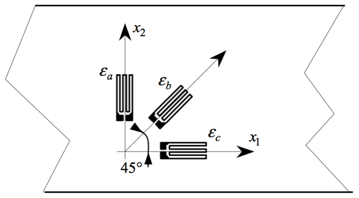

(1) Determine the strain tensor in the axis system $\left(x_1 ,x_2 ,x_3 \right)$.

(2) Determine the principal strains and draw a figure with the principal directions.

(3) Determine the matrix of the stress tensor in $\left(x_1 ,x_2 ,x_3 \right)$. 

(4) The solid is submitted to an additional uniaxial stress of 30 MPa along a direction defining an angle of +20° with  in the plane $\left(x_1 ,x_2 \right)$. 

Calculate the resulting stress tensor and its principal directions.

$E=210\;\textrm{GPa}$, $\nu =0\ldotp 3$

**(1)** we have $\epsilon_c =\varepsilon_{11}$ and $\epsilon_a =\epsilon_{22}$. The expression of the tensor is therefore :$\bar{\bar{\epsilon} } =\left\lbrack \begin{array}{ccc}
\epsilon_c  & \epsilon_{12}  & 0\\
\varepsilon_{12}  & \epsilon_a  & 0\\
0 & 0 & \epsilon_3 
\end{array}\right\rbrack$. We define the vector $\overrightarrow{n_b }$ such that $\bar{n_b } =\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{c}
1\\
1\\
0
\end{array}\right\rbrack$

The equation is therefore : $\varepsilon_b ={\bar{n_b } }^t \cdot \varepsilon \cdot \bar{n_b }$

$\varepsilon_3 =\frac{-\nu }{E}\left(\sigma_1 +\sigma_2 \right)$ and $\begin{array}{l}
E\varepsilon_1 =\sigma_1 -\nu \sigma_2 \\
E\varepsilon_2 =-\nu \sigma_1 +\sigma_2 
\end{array}$ 

then $\sigma_1 =E\frac{\varepsilon_1 +\nu \varepsilon_2 }{1-\nu^2 }$ and $\sigma_2 =E\frac{\varepsilon_2 +\nu \varepsilon_1 }{1-\nu^2 }$ reporting in the first equation leads to : $\varepsilon_3 =\frac{-\nu }{1-\nu }\left(\varepsilon_1 +\varepsilon_2 \right)$

syms ea eb ec e12 e3
e=[ec e12 0;e12 ea 0;0 0 e3];
nb=1/sqrt(2)*[1;1;0];
eqn=nb'*e*nb==eb;
res=solve(eqn,e12)

$$res = \mathrm{eb}-\frac{\mathrm{ea}}{2}-\frac{\mathrm{ec}}{2}$$

ea=1.5e-4;eb=2.25e-4;ec=1.6e-4;E=210e9;nu=0.3;
einc=eval(res)

einc = 7.0000e-05

e3=-nu/(1-nu)*(ea+ec)

e3 = -1.3286e-04

**(2) **Calcul directement sous matlab


e=[ec einc 0;einc ea 0;0 0 e3];
[vec e_p]=eigs(e)

vec =    -0.7319         0    0.6815
   -0.6815         0   -0.7319
         0    1.0000         0


e_p = 	1.0e+-3 *

    0.2252         0         0
         0   -0.1329         0
         0         0    0.0848


xI=vec(:,1); x1=[-1;0;0];
angle=acos(xI'*x1)*180/pi

angle = 42.9572

**3)** lets recall : $G=\frac{E}{2\left(1+\nu \right)}$    $\lambda =\frac{E\nu }{\left(1+\nu \right)\left(1-2\nu \right)}$  and $\bar{\bar{\sigma} } =\lambda \textrm{trace}\left(\bar{\bar{\varepsilon} } \right)\cdot \bar{\bar{I} } +2G\cdot \bar{\bar{\varepsilon} }$

G=E/(2*(1+nu));L=E*nu/((1+nu)*(1-2*nu));
sig=(L*trace(e)*eye(3)+2*G*e)/1e6

sig =    47.3077   11.3077         0
   11.3077   45.6923         0
         0         0   -0.0000


**(4)** on définit l'état de contrainte dû à la traction pure dans la direction donnée.


$$\tilde\sigma^c=\tilde\sigma^b+\tilde\sigma^a$$


$\bar{\bar{\sigma^{\left(2\right)} } } =\left\lbrack \begin{array}{ccc}
30 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$dans le repère $\left(x_4 ,x_5 ,x_3 \right)$. On cherche à évaluer cette même matrice dans le repère $\left(x_1 ,x_2 ,x_3 \right)$. Pour cela on définit la matrice rotation : $\textrm{rot}=\left\lbrack \begin{array}{ccc}
\cos \theta  & -\sin \theta  & 0\\
\sin \theta  & \cos \theta  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$avec $\theta =-20°$

Le tenseur devient : ${\textrm{rot}}^{-1} \cdot$$\sigma^{\left(2\right)} \cdot \textrm{rot}$ et il suffit de superposer au premier.

sig2_45=[30 0 0;0 0 0;0 0 0]*1e6;
theta=-20*pi/180;
rot=[cos(theta) -sin(theta) 0;sin(theta) cos(theta) 0;0 0 1];
sig2_12=rot'*sig2_45*rot

sig2_12 = 	1.0e+07 *

    2.6491    0.9642         0
    0.9642    0.3509         0
         0         0         0


sig_t_12=sig+sig2_12

sig_t_12 = 	1.0e+07 *

    2.6491    0.9642         0
    0.9642    0.3509         0
         0         0   -0.0000
